# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*Add your comemnts here..... be concise*

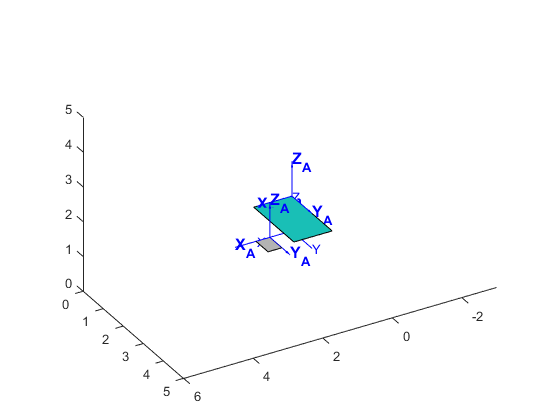

clear all

A= 1.1;
L = 2;

aux_A= 0.4;
aux_L = 0.6;

centro_cama = [0 0 1];
centro_aux = [1.5 1.5 1];

FA = eye(4);
FB = eye(4);
yaw = 0; %eje z
roll = 0; % eje x
pitch = 0; % eje y

yaw_aux = 0; %eje z
roll_aux = 0; % eje x
pitch_aux = 0; % eje y

mat_aux = [ 0 0 0 1; aux_A 0 0 1; aux_A aux_L 0 1; 0 aux_L 0 1]';
mat_cama = [ 0 0 0 1; A 0 0 1; A L 0 1; 0 L 0 1]';

r = rpy2r(roll, pitch, yaw,'deg');
r = r2t(r);

r_aux = rpy2r(roll_aux, pitch_aux, yaw_aux,'deg');
r_aux = r2t(r_aux);

FA = transl(centro_cama)*r; %cama 
FB = transl(centro_aux)*r_aux; %mesa aux

mat_cama = transl(centro_cama)*r*mat_cama;
mat_cama = mat_cama(1:3,:);

mat_aux = transl(centro_aux)*r_aux*mat_aux;
mat_aux = mat_aux(1:3,:);

hold on
s= fill3(mat_cama(1,:), mat_cama(2,:), mat_cama(3,:), [1 1 1 1]);
set(s,'facealpha',1);

s2= fill3(mat_aux(1,:), mat_aux(2,:), mat_aux(3,:), [0.7 0.7 0.7]);
set(s2,'facealpha',1);

trplot(eye(4)); % mundo
trplot(FA, ... % Plot frame FA with all the . See 'help trplot'
    'frame', 'A', ...
    'color', 'b',...
    'text_opts', {'FontSize', 12, 'FontWeight', 'bold'},...
     'length',1,...
    'arrow',...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[150,30],...
    'width', 1.2);
trplot(FB, ... % Plot frame FB with all the . See 'help trplot'
    'frame', 'A', ...
    'color', 'b',...
    'text_opts', {'FontSize', 12, 'FontWeight', 'bold'},...
     'length',1,...
    'arrow',...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[150,30],...
    'width', 1.2);

axis([-3 6 0 5 0 5])

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

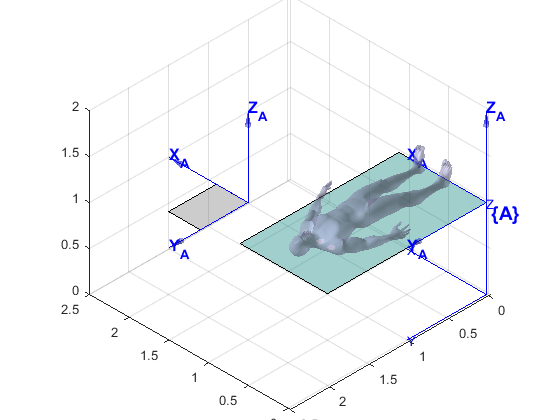

altura_human = 1.80;

load('SP_material/F_V_Human_Body.mat');
% Para redimencionar al cuerpo multiplicamos los vertices
max_y = max(V(:,2));

tamano = altura_human/max_y;

V = V*tamano;
% Buscamos la anchura después de hacer el escalado.
min_z = min(V(:,3));

%centramos al humano en la mesa
centrado = altura_human/2;

V(:,4) = ones(size(V,1),1); % Añadir fila de 1 para poder trasladar
V = V'; % Transponer para hacer la multiplicacion
V = transl(A/2,-centrado+L/2,-min_z)*V;
V = transl(centro_cama(1),centro_cama(2),centro_cama(3))*r*V;
V = V(1:3,:);
V = V';


stlPlot(V,F,'human')
alpha 0.4;
axis equal;

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

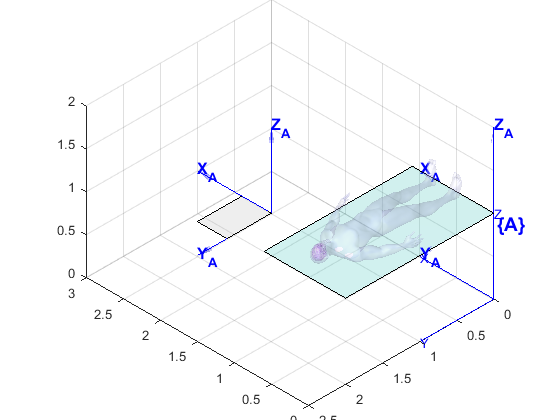

%fv = stlread('SP_material/Crani.stl');
load('Crani.mat');
tamano_crani = 0.075;

% Para redimencionar al cuerpo multiplicamos los vertices
max_y = max(fv.vertices(:,2));

tamano = tamano_crani/max_y;
%V2 = fv.vertices;
%fv.vertices = V2;
fv.vertices = fv.vertices*tamano;
% Buscamos la anchura después de hacer el escalado.
max_y = max(fv.vertices(:,2));
max_z = max(fv.vertices(:,3)); % para luego centrar la parte de arriba del craneo con la parte de arriba de la cabeza del humano

% añadimos el fiducial
fiducial_y = tamano_crani;  % calculamos la posición
fiducial_x = tamano_crani;

fv.vertices(:,4) = ones(size(fv.vertices,1),1); % Añadir fila de 1 para poder trasladar
fv.vertices = fv.vertices'; % Transponer para hacer la multiplicacion
fv.vertices = transl(A/2,L/2,-min_z)*trotx(-90,'deg')*fv.vertices; %rotamos y centramos a la mesa
fv.vertices = transl(0,centrado-max_z,0)*fv.vertices; % subimos para que este a la altura de la cabeza
fv.vertices = transl(centro_cama(1),centro_cama(2),centro_cama(3))*r*fv.vertices; % trasladamos a la posicion de la mesa



fv.vertices = fv.vertices(1:3,:);
fv.vertices = fv.vertices';
hold on

patch(fv,'FaceColor',       [0.7 0.5 0.9], ...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);
     
camlight('headlight');
material('shiny');

alpha 0.2;

axis([0 3 0 2.5 0 2])



%axis('image');
%view([-135 35]);

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

load('tumor_points.mat');

max_x_tumor = max(tumor(1,:))

max_x_tumor = 0.1587

min_x_tumor = min(tumor(1,:))

min_x_tumor = 0.1099


max_y_tumor = max(tumor(2,:))

max_y_tumor = 0.1463

min_y_tumor = min(tumor(2,:))

min_y_tumor = 0.0852


max_z_tumor = max(tumor(3,:))

max_z_tumor = 0.0672

min_z_tumor = min(tumor(3,:))

min_z_tumor = 0.0336


centro_tumor = [(max_x_tumor-min_x_tumor)/2,(max_y_tumor-min_y_tumor)/2,(max_z_tumor-min_z_tumor)/2]

centro_tumor =     0.0244    0.0306    0.0168


tumor = tumor';
tumor(:,4) = ones(size(tumor,1),1) % Añadir fila de 1 para poder trasladar

tumor =     0.1402    0.1463    0.0336    1.0000
    0.1454    0.1046    0.0336    1.0000
    0.1390    0.0973    0.0336    1.0000
    0.1341    0.1037    0.0336    1.0000
    0.1408    0.1130    0.0350    1.0000
    0.1460    0.1089    0.0350    1.0000
    0.1442    0.1011    0.0350    1.0000
    0.1376    0.0964    0.0350    1.0000
    0.1324    0.1017    0.0350    1.0000
    0.1379    0.1080    0.0364    1.0000


tumor = tumor' % Transponer para hacer la multiplicacion

tumor =     0.1402    0.1454    0.1390    0.1341    0.1408    0.1460    0.1442    0.1376    0.1324    0.1379    0.1463    0.1370    0.1318    0.1303    0.1387    0.1408    0.1309    0.1486    0.1399    0.1399    0.1410    0.1509    0.1292    0.1387    0.1390    0.1483    0.1442    0.1532    0.1292    0.1376    0.1535    0.1292    0.1384    0.1480    0.1442    0.1416    0.1442    0.1538    0.1280    0.1410    0.1434    0.1549    0.1280    0.1428    0.1419    0.1552    0.1263    0.1431    0.1439    0.1564
    0.1463    0.1046    0.0973    0.1037    0.1130    0.1089    0.1011    0.0964    0.1017    0.1080    0.1002    0.0950    0.1015    0.1098    0.0947    0.1138    0.1048    0.1054    0.0944    0.0941    0.1161    0.1046    0.1046    0.0930    0.1173    0.1158    0.1216    0.1057    0.1043    0.0906    0.1052    0.1046    0.1185    0.1170    0.1222    0.0883    0.1214    0.1057    0.1034    0.0872    0.1216    0.1054    0.1046    0.0866    0.1211    0.1034    0.1022    0.0860    0.1225 

tumor = transl(-centro_tumor(1),-centro_tumor(2),-centro_tumor(3))*tumor %rotamos y centramos a la mesa

tumor =     0.1158    0.1210    0.1146    0.1097    0.1164    0.1216    0.1199    0.1132    0.1081    0.1135    0.1219    0.1126    0.1074    0.1059    0.1143    0.1164    0.1065    0.1242    0.1155    0.1155    0.1167    0.1265    0.1048    0.1143    0.1146    0.1239    0.1199    0.1288    0.1048    0.1132    0.1291    0.1048    0.1141    0.1236    0.1199    0.1172    0.1199    0.1294    0.1036    0.1167    0.1190    0.1306    0.1036    0.1184    0.1175    0.1308    0.1019    0.1187    0.1196    0.1320
    0.1157    0.0740    0.0667    0.0731    0.0824    0.0783    0.0705    0.0659    0.0711    0.0775    0.0696    0.0644    0.0709    0.0792    0.0641    0.0832    0.0743    0.0749    0.0638    0.0636    0.0856    0.0740    0.0740    0.0624    0.0867    0.0853    0.0911    0.0751    0.0737    0.0601    0.0747    0.0740    0.0879    0.0864    0.0916    0.0578    0.0908    0.0751    0.0728    0.0566    0.0911    0.0749    0.0740    0.0560    0.0905    0.0728    0.0717    0.0554    0.0919 

x = tumor(1,:)

x =     0.1158    0.1210    0.1146    0.1097    0.1164    0.1216    0.1199    0.1132    0.1081    0.1135    0.1219    0.1126    0.1074    0.1059    0.1143    0.1164    0.1065    0.1242    0.1155    0.1155    0.1167    0.1265    0.1048    0.1143    0.1146    0.1239    0.1199    0.1288    0.1048    0.1132    0.1291    0.1048    0.1141    0.1236    0.1199    0.1172    0.1199    0.1294    0.1036    0.1167    0.1190    0.1306    0.1036    0.1184    0.1175    0.1308    0.1019    0.1187    0.1196    0.1320


y = tumor(2,:)

y =     0.1157    0.0740    0.0667    0.0731    0.0824    0.0783    0.0705    0.0659    0.0711    0.0775    0.0696    0.0644    0.0709    0.0792    0.0641    0.0832    0.0743    0.0749    0.0638    0.0636    0.0856    0.0740    0.0740    0.0624    0.0867    0.0853    0.0911    0.0751    0.0737    0.0601    0.0747    0.0740    0.0879    0.0864    0.0916    0.0578    0.0908    0.0751    0.0728    0.0566    0.0911    0.0749    0.0740    0.0560    0.0905    0.0728    0.0717    0.0554    0.0919    0.0725


z = tumor(3,:)

z =     0.0168    0.0168    0.0168    0.0168    0.0182    0.0182    0.0182    0.0182    0.0182    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0210    0.0210    0.0210    0.0210    0.0224    0.0224    0.0224    0.0224    0.0224    0.0224    0.0238    0.0238    0.0238    0.0238    0.0238    0.0238    0.0252    0.0252    0.0252    0.0252    0.0266    0.0266    0.0266    0.0266    0.0280    0.0280    0.0280    0.0280    0.0294    0.0294    0.0294


scatter3(x,y,z,'filled')
tumor = transl(A/2,L/2,-min_z_tumor)*trotx(-90,'deg')*tumor %rotamos y centramos a la mesa

tumor =     0.6658    0.6710    0.6646    0.6597    0.6664    0.6716    0.6699    0.6632    0.6581    0.6635    0.6719    0.6626    0.6574    0.6559    0.6643    0.6664    0.6565    0.6742    0.6655    0.6655    0.6667    0.6765    0.6548    0.6643    0.6646    0.6739    0.6699    0.6788    0.6548    0.6632    0.6791    0.6548    0.6641    0.6736    0.6699    0.6672    0.6699    0.6794    0.6536    0.6667    0.6690    0.6806    0.6536    0.6684    0.6675    0.6808    0.6519    0.6687    0.6696    0.6820
    1.0168    1.0168    1.0168    1.0168    1.0182    1.0182    1.0182    1.0182    1.0182    1.0196    1.0196    1.0196    1.0196    1.0196    1.0196    1.0196    1.0196    1.0196    1.0196    1.0210    1.0210    1.0210    1.0210    1.0224    1.0224    1.0224    1.0224    1.0224    1.0224    1.0238    1.0238    1.0238    1.0238    1.0238    1.0238    1.0252    1.0252    1.0252    1.0252    1.0266    1.0266    1.0266    1.0266    1.0280    1.0280    1.0280    1.0280    1.0294    1.0294 

x = tumor(1,:)

x =     0.6658    0.6710    0.6646    0.6597    0.6664    0.6716    0.6699    0.6632    0.6581    0.6635    0.6719    0.6626    0.6574    0.6559    0.6643    0.6664    0.6565    0.6742    0.6655    0.6655    0.6667    0.6765    0.6548    0.6643    0.6646    0.6739    0.6699    0.6788    0.6548    0.6632    0.6791    0.6548    0.6641    0.6736    0.6699    0.6672    0.6699    0.6794    0.6536    0.6667    0.6690    0.6806    0.6536    0.6684    0.6675    0.6808    0.6519    0.6687    0.6696    0.6820


y = tumor(2,:)

y =     1.0168    1.0168    1.0168    1.0168    1.0182    1.0182    1.0182    1.0182    1.0182    1.0196    1.0196    1.0196    1.0196    1.0196    1.0196    1.0196    1.0196    1.0196    1.0196    1.0210    1.0210    1.0210    1.0210    1.0224    1.0224    1.0224    1.0224    1.0224    1.0224    1.0238    1.0238    1.0238    1.0238    1.0238    1.0238    1.0252    1.0252    1.0252    1.0252    1.0266    1.0266    1.0266    1.0266    1.0280    1.0280    1.0280    1.0280    1.0294    1.0294    1.0294


z = tumor(3,:)

z =    -0.1493   -0.1076   -0.1003   -0.1067   -0.1160   -0.1119   -0.1041   -0.0995   -0.1047   -0.1111   -0.1032   -0.0980   -0.1045   -0.1128   -0.0977   -0.1168   -0.1079   -0.1085   -0.0974   -0.0972   -0.1192   -0.1076   -0.1076   -0.0960   -0.1203   -0.1189   -0.1247   -0.1087   -0.1073   -0.0937   -0.1083   -0.1076   -0.1215   -0.1200   -0.1252   -0.0914   -0.1244   -0.1087   -0.1064   -0.0902   -0.1247   -0.1085   -0.1076   -0.0896   -0.1241   -0.1064   -0.1053   -0.0890   -0.1255   -0.1061


scatter3(x,y,z,'filled')
tumor = transl(0,centrado-max_z_tumor,0)*tumor % subimos para que este a la altura de la cabeza

tumor =     0.6658    0.6710    0.6646    0.6597    0.6664    0.6716    0.6699    0.6632    0.6581    0.6635    0.6719    0.6626    0.6574    0.6559    0.6643    0.6664    0.6565    0.6742    0.6655    0.6655    0.6667    0.6765    0.6548    0.6643    0.6646    0.6739    0.6699    0.6788    0.6548    0.6632    0.6791    0.6548    0.6641    0.6736    0.6699    0.6672    0.6699    0.6794    0.6536    0.6667    0.6690    0.6806    0.6536    0.6684    0.6675    0.6808    0.6519    0.6687    0.6696    0.6820
    1.8496    1.8496    1.8496    1.8496    1.8510    1.8510    1.8510    1.8510    1.8510    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8538    1.8538    1.8538    1.8538    1.8552    1.8552    1.8552    1.8552    1.8552    1.8552    1.8566    1.8566    1.8566    1.8566    1.8566    1.8566    1.8580    1.8580    1.8580    1.8580    1.8594    1.8594    1.8594    1.8594    1.8608    1.8608    1.8608    1.8608    1.8622    1.8622 

x = tumor(1,:)

x =     0.6658    0.6710    0.6646    0.6597    0.6664    0.6716    0.6699    0.6632    0.6581    0.6635    0.6719    0.6626    0.6574    0.6559    0.6643    0.6664    0.6565    0.6742    0.6655    0.6655    0.6667    0.6765    0.6548    0.6643    0.6646    0.6739    0.6699    0.6788    0.6548    0.6632    0.6791    0.6548    0.6641    0.6736    0.6699    0.6672    0.6699    0.6794    0.6536    0.6667    0.6690    0.6806    0.6536    0.6684    0.6675    0.6808    0.6519    0.6687    0.6696    0.6820


y = tumor(2,:)

y =     1.8496    1.8496    1.8496    1.8496    1.8510    1.8510    1.8510    1.8510    1.8510    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8538    1.8538    1.8538    1.8538    1.8552    1.8552    1.8552    1.8552    1.8552    1.8552    1.8566    1.8566    1.8566    1.8566    1.8566    1.8566    1.8580    1.8580    1.8580    1.8580    1.8594    1.8594    1.8594    1.8594    1.8608    1.8608    1.8608    1.8608    1.8622    1.8622    1.8622


z = tumor(3,:)

z =    -0.1493   -0.1076   -0.1003   -0.1067   -0.1160   -0.1119   -0.1041   -0.0995   -0.1047   -0.1111   -0.1032   -0.0980   -0.1045   -0.1128   -0.0977   -0.1168   -0.1079   -0.1085   -0.0974   -0.0972   -0.1192   -0.1076   -0.1076   -0.0960   -0.1203   -0.1189   -0.1247   -0.1087   -0.1073   -0.0937   -0.1083   -0.1076   -0.1215   -0.1200   -0.1252   -0.0914   -0.1244   -0.1087   -0.1064   -0.0902   -0.1247   -0.1085   -0.1076   -0.0896   -0.1241   -0.1064   -0.1053   -0.0890   -0.1255   -0.1061


scatter3(x,y,z,'filled')
tumor = transl(centro_cama(1),centro_cama(2),centro_cama(3))*r*tumor % trasladamos a la posicion de la mesa

tumor =     0.6658    0.6710    0.6646    0.6597    0.6664    0.6716    0.6699    0.6632    0.6581    0.6635    0.6719    0.6626    0.6574    0.6559    0.6643    0.6664    0.6565    0.6742    0.6655    0.6655    0.6667    0.6765    0.6548    0.6643    0.6646    0.6739    0.6699    0.6788    0.6548    0.6632    0.6791    0.6548    0.6641    0.6736    0.6699    0.6672    0.6699    0.6794    0.6536    0.6667    0.6690    0.6806    0.6536    0.6684    0.6675    0.6808    0.6519    0.6687    0.6696    0.6820
    1.8496    1.8496    1.8496    1.8496    1.8510    1.8510    1.8510    1.8510    1.8510    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8538    1.8538    1.8538    1.8538    1.8552    1.8552    1.8552    1.8552    1.8552    1.8552    1.8566    1.8566    1.8566    1.8566    1.8566    1.8566    1.8580    1.8580    1.8580    1.8580    1.8594    1.8594    1.8594    1.8594    1.8608    1.8608    1.8608    1.8608    1.8622    1.8622 

x = tumor(1,:)

x =     0.6658    0.6710    0.6646    0.6597    0.6664    0.6716    0.6699    0.6632    0.6581    0.6635    0.6719    0.6626    0.6574    0.6559    0.6643    0.6664    0.6565    0.6742    0.6655    0.6655    0.6667    0.6765    0.6548    0.6643    0.6646    0.6739    0.6699    0.6788    0.6548    0.6632    0.6791    0.6548    0.6641    0.6736    0.6699    0.6672    0.6699    0.6794    0.6536    0.6667    0.6690    0.6806    0.6536    0.6684    0.6675    0.6808    0.6519    0.6687    0.6696    0.6820


y = tumor(2,:)

y =     1.8496    1.8496    1.8496    1.8496    1.8510    1.8510    1.8510    1.8510    1.8510    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8524    1.8538    1.8538    1.8538    1.8538    1.8552    1.8552    1.8552    1.8552    1.8552    1.8552    1.8566    1.8566    1.8566    1.8566    1.8566    1.8566    1.8580    1.8580    1.8580    1.8580    1.8594    1.8594    1.8594    1.8594    1.8608    1.8608    1.8608    1.8608    1.8622    1.8622    1.8622


z = tumor(3,:)

z =     0.8507    0.8924    0.8997    0.8933    0.8840    0.8881    0.8959    0.9005    0.8953    0.8889    0.8968    0.9020    0.8955    0.8872    0.9023    0.8832    0.8921    0.8915    0.9026    0.9028    0.8808    0.8924    0.8924    0.9040    0.8797    0.8811    0.8753    0.8913    0.8927    0.9063    0.8917    0.8924    0.8785    0.8800    0.8748    0.9086    0.8756    0.8913    0.8936    0.9098    0.8753    0.8915    0.8924    0.9104    0.8759    0.8936    0.8947    0.9110    0.8745    0.8939


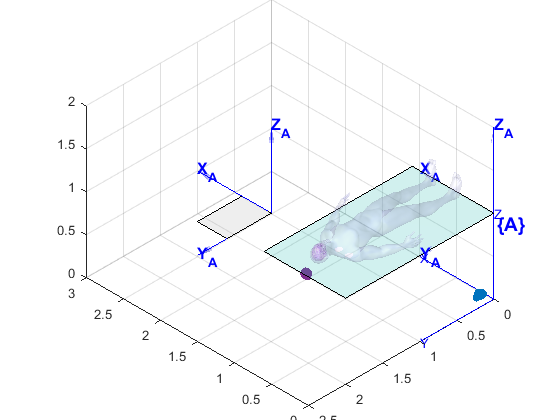

scatter3(x,y,z,'filled')

*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

%% put your code Here

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Add your comemnts here.....be concise*

%% put your code Here

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts her**e.....be concise*

%% put your code Here

10.- Prepare a script that perform trepanation.

*Add your comemnts her**e.....be concise*

%% put your code Here

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts her**e.....be concise*

%% put your code Here

*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*Add your comemnts her**e.....be concise*

%% put your code Here

13.- Print the tumor points in Robot Frame.

*Add your comemnts her**e.....be concise*

%% put your code Here

14.-Use the script that perform a biopsy. Zoom in the scene

*Add your comemnts her**e.....be concise*

%% put your code Here

15.- Use the  script that perform trepanation.

*Add your comemnts her**e.....be concise*

%% put your code Here

16.- Use the script that perform tumor burning with the laser.

*Add your comemnts her**e.....be concise*

%% put your code Here